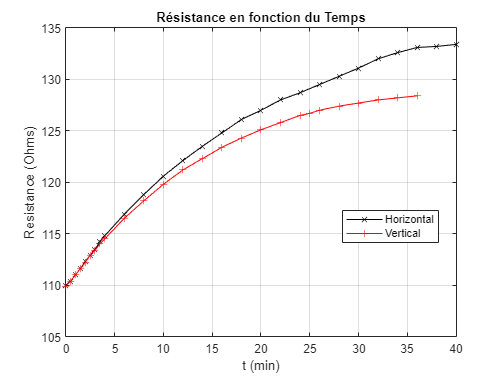

clc

th= [0 0.5 1 1.5 2 2.5 3 3.5 4 6 8 10 12 14 16 18 20 22 24 26 28 30 32 34 36 38 40];
Rth=[110 110.4 111 111.6 112.3 112.9 113.5 114.2 114.8 116.9 118.8 120.6 122.1 123.5 124.8 126.1 127 128 128.7 129.5 130.3 131.1 132 132.6 133.1 133.2 133.4];
tv= [0 0.5 1 1.5 2 2.5 3 3.5 4 6 8 10 12 14 16 18 20 22 24 25 26 28 30 32 34 36];
Rtv=[109.9 110.4 111 111.6 112.2 112.9 113.4 114 114.5 116.5 118.2 119.8 121.2 122.3 123.4 124.3 125.1 125.8 126.5 126.7 127 127.4 127.7 128 128.2 128.4];

plot(th,Rth,'kx-',tv,Rtv,'r+-')
title('Résistance en fonction du Temps')
legend(["Horizontal","Vertical"],'Location','best')
xlabel('t (min)'); ylabel('Resistance (Ohms)')
grid on

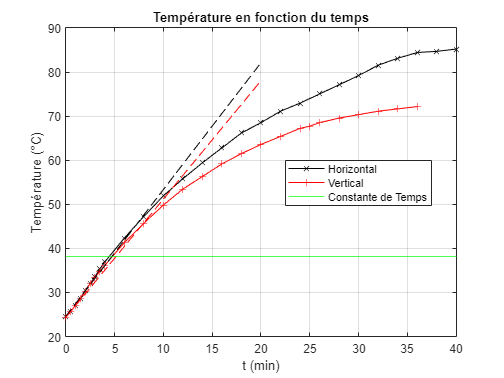



R0=100.39;A=3.9083e-3;B=-5.775e-7;
Th = (-A+(A^2-4*B*(1-(Rth/R0))).^(1/2))/(2*B);
Tv = (-A+(A^2-4*B*(1-(Rtv/R0))).^(1/2))/(2*B);

% Tangente
p=linspace(0,20,40);
tangente1 = p*(Th(12)-Th(1))/(th(12)-th(2))+Th(1);
tangente2 = p*(Tv(12)-Tv(1))/(tv(12)-tv(2))+Tv(1);

plot(th,Th,'kx-',tv,Tv,'r+-',p,tangente1,'k--',p,tangente2,'r--')
yline((Th(end)-Th(1))*(63/100),'g-')
title('Température en fonction du temps')
legend(["Horizontal","Vertical","","","Constante de Temps"],'Location','best')
xlabel('t (min)'); ylabel('Température (°C)')
grid on

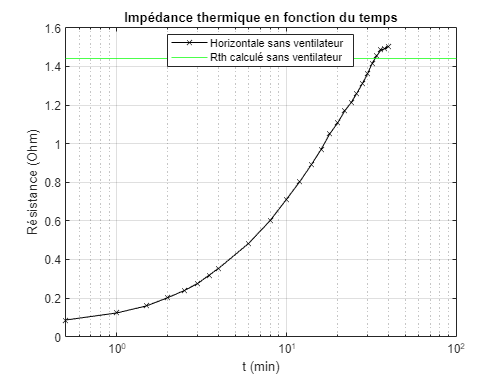



P = 42*1;
Zh = (Th-22)/P;

semilogx(th,Zh,'kx-')
yline(1.44,'g')
legend("Horizontale sans ventilateur","Rth calculé sans ventilateur","Location","best")
xlabel('t (min)'); ylabel('Résistance (Ohm)')
title("Impédance thermique en fonction du temps")
grid on